# Module 2: Action Functional Gradient Descent (AFGD) algorithm

clear all

## Load model

lattice_edge = 2; 
model_name = 'Schlogl_1_'+string(lattice_edge)

model_name = "Schlogl_1_2"

plotnam = "2-Schlogl model"

plotnam = "2-Schlogl model"

model_name = "Selkov"

model_name = "Selkov"

plotnam = "Selkov model"

plotnam = "Selkov model"

model_name = "SYN3_FINAL"
plotnam = "12-D Syntrophy model"

model_name = "Cluster_3_catalyst"
plotnam = "3-D Cluster model with catalysis"

model_name = "Cluster_3_catalyst_w_temp"
plotnam = "3-D Cluster model with catalysis & templating"

#### Load ..._Ham.mat from 'data' folder

load('..\Data\'+model_name+'_Ham.mat')

#### Load heteroclinic network

i = row in hc_net. j = column in hc_net - 1 

load('..\Data\' + model_name + '_hcnet.mat')
pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cc} 68 & 8\\ 80 & 2\\ 48 & 18 \end{array}\right)$$

hc_net

hc_net =      1     3     2


i = 1; j = 1;
sad_pt = i; stab_pt_choice = j;

i = 1; j = 2;
sad_pt = i; stab_pt_choice = j;

#### Load initial condition

Straight 

load('..\Data\' + model_name + '_initcond_'+string(i)...
        +'_'+string(j)+'straight.mat')

Spiral

load('..\Data\' + model_name + '_initcond_'+string(i)...
+'_'+string(j)+'spiral.mat')

#### Sample space uniform and plot

%Space uniform sampling
traj_pts = 2000;
traj_ic = double(traj_ic);
[traj,len_curve_prime] = space_uniform_sampling(traj_ic,traj_pts);

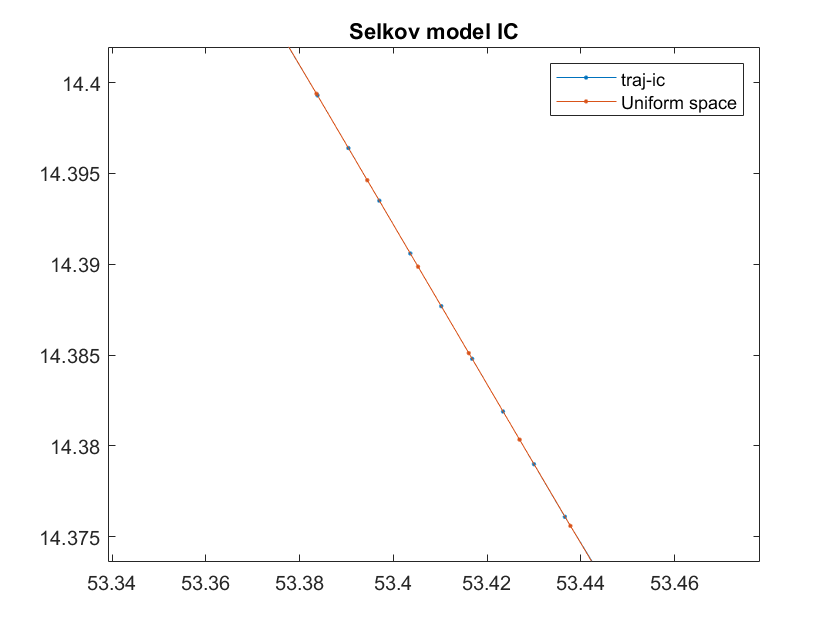

%Plot
figure()
plot(traj_ic(:,1),traj_ic(:,2:end),'.-')
hold on
plot(traj(:,1),traj(:,2:end),'.-')
hold off
legend('traj-ic','Uniform space')
title(plotnam + ' IC')

## Initialize Descender

%number of points in trajectory
traj_pts = size(traj,1);

%Initialize arrays for saving and delta_x_s
Initialize_descender

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


S_arr = 0.4053


%Save data to file in the data folder
savenam = '..\Data\' + model_name + '_descend_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'spiral_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "..\Data\Selkov_descend_1_1spiral_2000_08-Jul-2022.mat"

save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
+'_'+string(stab_pt_choice)+'_PS_traj_IC.png'

save_plot_name = "Plots/Selkov_1_1_PS_traj_IC.png"

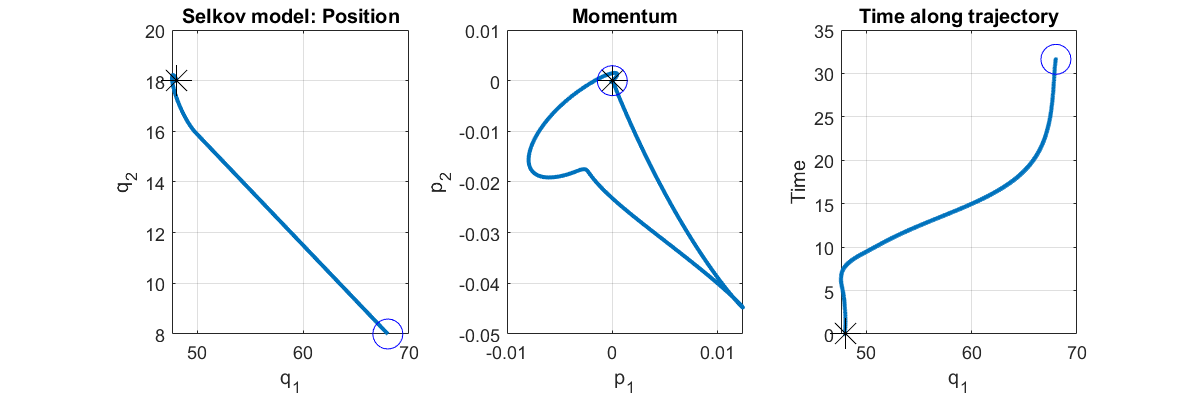

plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name);

diff(t_traj)

ans =     0.2690
    0.2609
    0.2526
    0.2442
    0.2357
    0.2271
    0.2184
    0.2095
    0.2005
    0.1915


min(diff(t_traj))

ans = 0.0053